GSM_st.name='GSM'; 
GSM_st.lat=35.63;
GSM_st.lon=-83.94;
GSM_st.alt=810;
GSM_st.env='con';
GSM_st.footp='F';

GSM_rd=read_betsy('GSM_head',GSM_st.name);

datevec(GSM_rd.Time(1))

ans =         1993           4           2           0           0           0

datevec(GSM_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(GSM_rd.U_S,[5, 50, 95])

ans =    40.1770   73.0700   98.2380

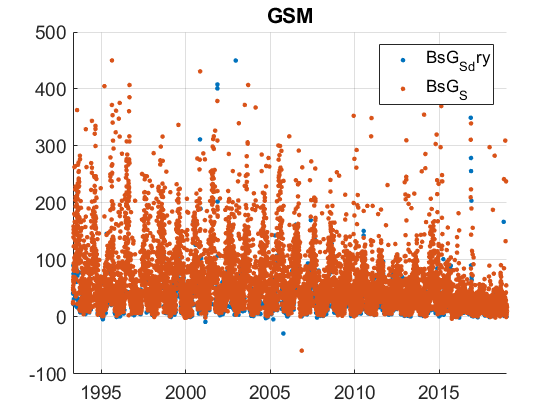

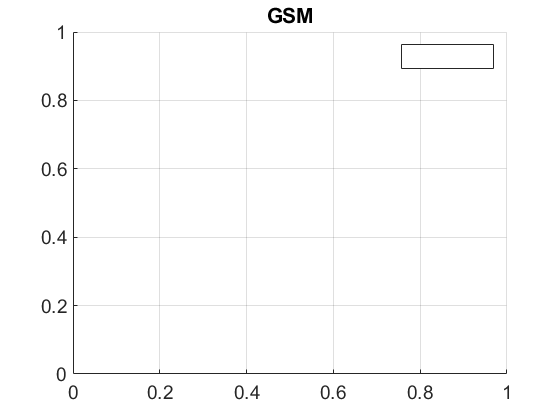

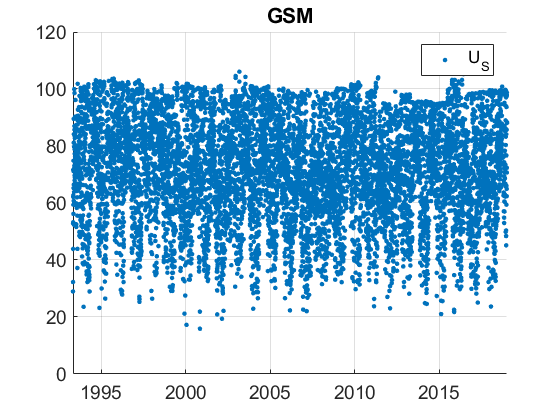

plotFigControl(GSM_rd,GSM_st.name);

% 1 size cut, 
% sc: ok, clear seasonal cycle, max in summer, some negatives

lambdaSC=[450;550;700]*ones(1,4); lambdaAE3=[467;530;660]*ones(1,4); lambdaAE7=[370 470 520 590 660 880 950]; GSM_cal=compute_exp_SSA(GSM_rd,lambdaSC, lambdaAE3); plotFigControl_cal(GSM_cal, GSM_st.name);

%Questions:
%problems:

%instrumental change in June 2015 ? seems to have a rupture October 2015

GSM_tr=GSM_rd;
GSM_tr.y=year(GSM_tr.Time);
%eneleve une valeur de 2019
GSM_tr=GSM_tr(1:end-1,:);
% begin at the beginning of a year:1994
%end year: 2014
P=timerange('1994-01-01','2019-01-01');
GSM_tr=GSM_tr(P,:);

names=fieldnames(GSM_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    GSM_tr.(N{i})=[];
end

P2=timerange('2014-05-01','2014-10-31');
GSM_tr.BsG_S(P2)=NaN;

% dry: very low data coverage in end summer autumn
%otherwise seems ok

GSM_result= all_trend_STN(GSM_tr,GSM_st); 

GSM_result_D=GSM_result;